% EEP557_HW2
% Qingchuan Hou
% 10/16/2022

## Nonlinear State Space Block Diagram

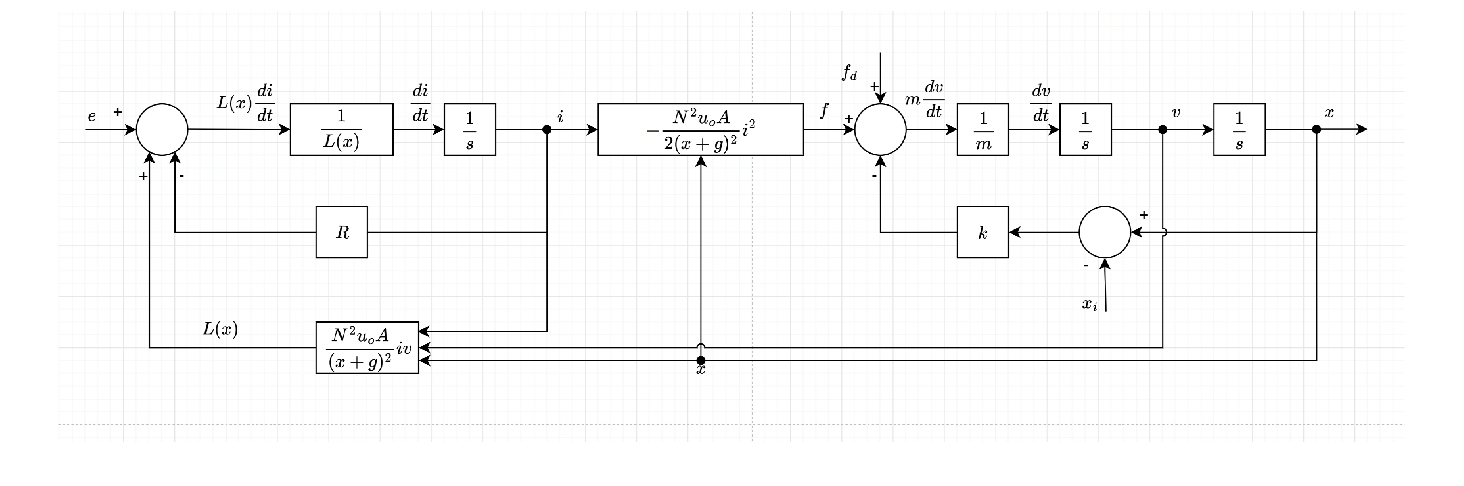

imshow("HW2/EEP557_HW2P1.png")

## Operating Point Block Diagram

imshow("HW2/EEP557_HW2P1.png")

## Analyze


syms i i_dot x x_dot v v_dot e f_d e N mu_0 A x g R m x_i K 
syms Delta_I Delta_V Delta_X Delta_E Delta_Fd s e_op i_op v_op x_op e_op fd_op fr

% Nonlinear State Space Equations
L_x = N^2*mu_0*A / (x + g) 

$$L\_x = \frac{A\,N^{2}\,\mu_{0}}{g+x}$$


eq1 = e == i*R + L_x*i_dot - L_x*i*v/(x+g)              % Voltage loop

$$eq1 = e=R\,i+\frac{A\,N^{2}\,\dot{i}\,\mu_{0}}{g+x}-\frac{A\,N^{2}\,i\,\mu_{0}\,v}{{\left(g+x\right)}^{2}}$$

eq2 = m*v_dot == f_d - (1/2)*L_x*i^2/(x+g) - K*(x-x_i)  % Newton's Law

$$eq2 = m\,\dot{v}=f_{d}-K\,\left(x-x_{i}\right)-\frac{A\,N^{2}\,i^{2}\,\mu_{0}}{2\,{\left(g+x\right)}^{2}}$$


% i_dot, v_dot
i_dot = simplify(solve(eq1, i_dot))

$$i\_dot = \frac{\left(g+x\right)\,\left(e-R\,i+\frac{A\,N^{2}\,i\,\mu_{0}\,v}{{\left(g+x\right)}^{2}}\right)}{A\,N^{2}\,\mu_{0}}$$

v_dot = solve(eq2, v_dot)

$$v\_dot = -\frac{K\,\left(x-x_{i}\right)-f_{d}+\frac{A\,N^{2}\,i^{2}\,\mu_{0}}{2\,{\left(g+x\right)}^{2}}}{m}$$

## Operating Point

% Partial
i_dot_di = simplify(expand(diff(i_dot, i)))

$$i\_dot\_di = -\frac{-A\,\mu_{0}\,v\,N^{2}+R\,g^{2}+2\,R\,g\,x+R\,x^{2}}{A\,N^{2}\,\mu_{0}\,\left(g+x\right)}$$

i_dot_dv = expand(diff(i_dot, v))

$$i\_dot\_dv = \frac{i}{g+x}$$

i_dot_dx = expand(diff(i_dot, x))

$$i\_dot\_dx = \frac{e}{A\,N^{2}\,\mu_{0}}-\frac{i\,v}{g^{2}+2\,g\,x+x^{2}}-\frac{R\,i}{A\,N^{2}\,\mu_{0}}$$

i_dot_de = simplify(expand(diff(i_dot, e)))

$$i\_dot\_de = \frac{g+x}{A\,N^{2}\,\mu_{0}}$$

i_dot_df_d = expand(diff(i_dot, f_d))

$$i\_dot\_df\_d = 0$$


v_dot_di = simplify(expand(diff(v_dot, i)))

$$v\_dot\_di = -\frac{A\,N^{2}\,i\,\mu_{0}}{m\,{\left(g+x\right)}^{2}}$$

v_dot_dv = expand(diff(v_dot, v))

$$v\_dot\_dv = 0$$

v_dot_dx = diff(v_dot, x)

$$v\_dot\_dx = -\frac{K-\frac{A\,N^{2}\,i^{2}\,\mu_{0}}{{\left(g+x\right)}^{3}}}{m}$$

v_dot_de = expand(diff(v_dot, e))

$$v\_dot\_de = 0$$

v_dot_df_d = expand(diff(v_dot, f_d))

$$v\_dot\_df\_d = \frac{1}{m}$$



% Operating point LaPlace domain equations
eq3 = s*Delta_I == Delta_I*i_dot_di + Delta_V*i_dot_dv + Delta_X*i_dot_dx + Delta_E*i_dot_de

$$eq3 = \begin{array}{l} \Delta_{I}\,s=\frac{\Delta_{V}\,i}{g+x}-\Delta_{X}\,\left(\frac{i\,v}{g^{2}+2\,g\,x+x^{2}}-\frac{e}{\sigma_{1}}+\frac{R\,i}{\sigma_{1}}\right)+\frac{\Delta_{E}\,\left(g+x\right)}{\sigma_{1}}-\frac{\Delta_{I}\,\left(-A\,\mu_{0}\,v\,N^{2}+R\,g^{2}+2\,R\,g\,x+R\,x^{2}\right)}{A\,N^{2}\,\mu_{0}\,\left(g+x\right)}\\ \mathrm{where}\\ \sigma_{1}=A\,N^{2}\,\mu_{0} \end{array}$$

eq4 = s*Delta_V == Delta_I*v_dot_di + Delta_V*v_dot_dv + Delta_X*v_dot_dx + Delta_Fd*v_dot_df_d

$$eq4 = \Delta_{V}\,s=\frac{\Delta_{\mathrm{Fd}}}{m}-\frac{\Delta_{X}\,\left(K-\frac{A\,N^{2}\,i^{2}\,\mu_{0}}{{\left(g+x\right)}^{3}}\right)}{m}-\frac{A\,\Delta_{I}\,N^{2}\,i\,\mu_{0}}{m\,{\left(g+x\right)}^{2}}$$

eq5 = s*Delta_X == Delta_V

$$eq5 = \Delta_{X}\,s=\Delta_{V}$$



% Solve Delta_X
eqs = [eq3, eq4, eq5]

$$eqs = \begin{array}{l} \left(\begin{array}{ccc} \Delta_{I}\,s=\frac{\Delta_{V}\,i}{g+x}-\Delta_{X}\,\left(\frac{i\,v}{g^{2}+2\,g\,x+x^{2}}-\frac{e}{\sigma_{1}}+\frac{R\,i}{\sigma_{1}}\right)+\frac{\Delta_{E}\,\left(g+x\right)}{\sigma_{1}}-\frac{\Delta_{I}\,\left(-A\,\mu_{0}\,v\,N^{2}+R\,g^{2}+2\,R\,g\,x+R\,x^{2}\right)}{A\,N^{2}\,\mu_{0}\,\left(g+x\right)} & \Delta_{V}\,s=\frac{\Delta_{\mathrm{Fd}}}{m}-\frac{\Delta_{X}\,\left(K-\frac{A\,N^{2}\,i^{2}\,\mu_{0}}{{\left(g+x\right)}^{3}}\right)}{m}-\frac{A\,\Delta_{I}\,N^{2}\,i\,\mu_{0}}{m\,{\left(g+x\right)}^{2}} & \Delta_{X}\,s=\Delta_{V} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=A\,N^{2}\,\mu_{0} \end{array}$$


S = subs(solve(eqs, [Delta_I, Delta_V, Delta_X]), [x i v e f_d], [x_op i_op v_op e_op fd_op])

S = struct with fields:
    Delta_I: (A*Delta_Fd*mu_0*N^2*g*i_op*s - A*Delta_E*mu_0*N^2*i_op^2 + A*Delta_Fd*mu_0*N^2*i_op*s*x_op - A*Delta_Fd*mu_0*v_op*N^2*i_op + Delta_E*m*g^3*s^2 + Delta_E*K*g^3 - Delta_Fd*R*g^2*i_op + 3*Delta_E*m*g^2*s^2*x_op + 3*Delta_E*K*g^2*x_op + Delt…
    Delta_V: (s*(g + x_op)*(Delta_Fd*R*g^2 + Delta_Fd*R*x_op^2 + 2*Delta_Fd*R*g*x_op - A*Delta_E*N^2*i_op*mu_0 - A*Delta_Fd*N^2*mu_0*v_op + A*Delta_Fd*N^2*g*mu_0*s + A*Delta_Fd*N^2*mu_0*s*x_op))/(A*m*mu_0*N^2*g^2*s^3 + A*K*mu_0*N^2*g^2*s + 2*A*m*mu_0*…
    Delta_X: ((g + x_op)*(Delta_Fd*R*g^2 + Delta_Fd*R*x_op^2 + 2*Delta_Fd*R*g*x_op - A*Delta_E*N^2*i_op*mu_0 - A*Delta_Fd*N^2*mu_0*v_op + A*Delta_Fd*N^2*g*mu_0*s + A*Delta_Fd*N^2*mu_0*s*x_op))/(A*m*mu_0*N^2*g^2*s^3 + A*K*mu_0*N^2*g^2*s + 2*A*m*mu_0*N^…



EQ1 = Delta_X == collect(S.Delta_X, [Delta_E, Delta_Fd])

$$EQ1 = \begin{array}{l} \Delta_{X}=\left(-\frac{A\,N^{2}\,i_{\mathrm{op}}\,\mu_{0}\,\left(g+x_{\mathrm{op}}\right)}{\sigma_{1}}\right)\,\Delta_{E}+\frac{\left(g+x_{\mathrm{op}}\right)\,\left(A\,\mu_{0}\,s\,N^{2}\,g+A\,\mu_{0}\,s\,N^{2}\,x_{\mathrm{op}}-A\,\mu_{0}\,v_{\mathrm{op}}\,N^{2}+R\,g^{2}+2\,R\,g\,x_{\mathrm{op}}+R\,{x_{\mathrm{op}}}^{2}\right)}{\sigma_{1}}\,\Delta_{\mathrm{Fd}}\\ \mathrm{where}\\ \sigma_{1}=A\,m\,\mu_{0}\,N^{2}\,g^{2}\,s^{3}+A\,K\,\mu_{0}\,N^{2}\,g^{2}\,s+2\,A\,m\,\mu_{0}\,N^{2}\,g\,s^{3}\,x_{\mathrm{op}}-A\,m\,\mu_{0}\,v_{\mathrm{op}}\,N^{2}\,g\,s^{2}+2\,A\,K\,\mu_{0}\,N^{2}\,g\,s\,x_{\mathrm{op}}-A\,K\,\mu_{0}\,v_{\mathrm{op}}\,N^{2}\,g-2\,A\,R\,\mu_{0}\,N^{2}\,{i_{\mathrm{op}}}^{2}+A\,e_{\mathrm{op}}\,\mu_{0}\,N^{2}\,i_{\mathrm{op}}+A\,m\,\mu_{0}\,N^{2}\,s^{3}\,{x_{\mathrm{op}}}^{2}-A\,m\,\mu_{0}\,v_{\mathrm{op}}\,N^{2}\,s^{2}\,x_{\mathrm{op}}+A\,K\,\mu_{0}\,N^{2}\,s\,{x_{\mathrm{op}}}^{2}-A\,K\,\mu_{0}\,v_{\mathrm{op}}\,N^{2}\,x_{\mathrm{op}}+R\,m\,g^{3}\,s^{2}+K\,R\,g^{3}+3\,R\,m\,g^{2}\,s^{2}\,x_{\mathrm{op}}+3\,K\,R\,g^{2}\,x_{\mathrm{op}}+3\,R\,m\,g\,s^{2}\,{x_{\mathrm{op}}}^{2}+3\,K\,R\,g\,{x_{\mathrm{op}}}^{2}+R\,m\,s^{2}\,{x_{\mathrm{op}}}^{3}+K\,R\,{x_{\mathrm{op}}}^{3} \end{array}$$

% Delta_Fd/Delta_X
subDelta_X = children(rhs(EQ1))

subDelta_X = 1×2 cell array
    {[(-(A*N^2*i_op*mu_0*(g + x_op))/(A*m*mu_0*N^2*g^2*s^3 + A*K*mu_0*N^2*g^2*s + 2*A*m*mu_0*N^2*g*s^3*x_op - A*m*mu_0*v_op*N^2*g*s^2 + 2*A*K*mu_0*N^2*g*s*x_op - A*K*mu_0*v_op*N^2*g - 2*A*R*mu_0*N^2*i_op^2 + A*e_op*mu_0*N^2*i_op + A*m*mu_0*N^2*s^3*x_op^2 - A*m*mu_0*v_op*N^2*s^2*x_op + A*K*mu_0*N^2*s*x_op^2 - A*K*mu_0*v_op*N^2*x_op + R*m*g^3*s^2 + K*R*g^3 + 3*R*m*g^2*s^2*x_op + 3*K*R*g^2*x_op + 3*R*m*g*s^2*x_op^2 + 3*K*R*g*x_op^2 + R*m*s^2*x_op^3 + K*R*x_op^3))*Delta_E]}    {[(((g + x_op)*(A*mu_0*s*N^2*g + A*mu_0*s*N^2*x_op - A*mu_0*v_op*N^2 + R*g^2 + 2*R*g*x_op + R*x_op^2))/(A*m*mu_0*N^2*g^2*s^3 + A*K*mu_0*N^2*g^2*s + 2*A*m*mu_0*N^2*g*s^3*x_op - A*m*mu_0*v_op*N^2*g*s^2 + 2*A*K*mu_0*N^2*g*s*x_op - A*K*mu_0*v_op*N^2*g - 2*A*R*mu_0*N^2*i_op^2 + A*e_op*mu_0*N^2*i_op + A*m*mu_0*N^2*s^3*x_op^2 - A*m*mu_0*v_op*N^2*s^2*x_op + A*K*mu_0*N^2*s*x_op^2 - A*K*mu_0*v_op*N^2*x_op + R*m*g^3*s^2 + K*R*g^3 + 3*R*m*g^2*s^2*x_op + 3*K*R*g^2*x_op + 3*R*m*g*s^2*x_op^2 + 3*K*R*g*x_

EQ2 = Delta_Fd/Delta_X == Delta_Fd/subDelta_X{2}

$$EQ2 = \frac{\Delta_{\mathrm{Fd}}}{\Delta_{X}}=\frac{A\,m\,\mu_{0}\,N^{2}\,g^{2}\,s^{3}+A\,K\,\mu_{0}\,N^{2}\,g^{2}\,s+2\,A\,m\,\mu_{0}\,N^{2}\,g\,s^{3}\,x_{\mathrm{op}}-A\,m\,\mu_{0}\,v_{\mathrm{op}}\,N^{2}\,g\,s^{2}+2\,A\,K\,\mu_{0}\,N^{2}\,g\,s\,x_{\mathrm{op}}-A\,K\,\mu_{0}\,v_{\mathrm{op}}\,N^{2}\,g-2\,A\,R\,\mu_{0}\,N^{2}\,{i_{\mathrm{op}}}^{2}+A\,e_{\mathrm{op}}\,\mu_{0}\,N^{2}\,i_{\mathrm{op}}+A\,m\,\mu_{0}\,N^{2}\,s^{3}\,{x_{\mathrm{op}}}^{2}-A\,m\,\mu_{0}\,v_{\mathrm{op}}\,N^{2}\,s^{2}\,x_{\mathrm{op}}+A\,K\,\mu_{0}\,N^{2}\,s\,{x_{\mathrm{op}}}^{2}-A\,K\,\mu_{0}\,v_{\mathrm{op}}\,N^{2}\,x_{\mathrm{op}}+R\,m\,g^{3}\,s^{2}+K\,R\,g^{3}+3\,R\,m\,g^{2}\,s^{2}\,x_{\mathrm{op}}+3\,K\,R\,g^{2}\,x_{\mathrm{op}}+3\,R\,m\,g\,s^{2}\,{x_{\mathrm{op}}}^{2}+3\,K\,R\,g\,{x_{\mathrm{op}}}^{2}+R\,m\,s^{2}\,{x_{\mathrm{op}}}^{3}+K\,R\,{x_{\mathrm{op}}}^{3}}{\left(g+x_{\mathrm{op}}\right)\,\left(A\,\mu_{0}\,s\,N^{2}\,g+A\,\mu_{0}\,s\,N^{2}\,x_{\mathrm{op}}-A\,\mu_{0}\,v_{\mathrm{op}}\,N^{2}+R\,g^{2}+2\,R\,g\,x_{\mathrm{op}}+R\,{x_{\mathrm{op}}}^{2}\right)}$$


% Operation point
eq6 = subs((1/2)*L_x*i^2/(x+g) - K*(x-x_i) == 0, [x i], [x_op i_op])

$$eq6 = K\,\left(x_{i}-x_{\mathrm{op}}\right)+\frac{A\,N^{2}\,{i_{\mathrm{op}}}^{2}\,\mu_{0}}{2\,{\left(g+x_{\mathrm{op}}\right)}^{2}}=0$$


i_op_x = solve(eq6, i_op)

$$i\_op\_x = \left(\begin{array}{c} \frac{\sqrt{2}\,\sqrt{-K}\,\left(g+x_{\mathrm{op}}\right)\,\sqrt{x_{i}-x_{\mathrm{op}}}}{\sqrt{A}\,N\,\sqrt{\mu_{0}}}\\ -\frac{\sqrt{2}\,\sqrt{-K}\,\left(g+x_{\mathrm{op}}\right)\,\sqrt{x_{i}-x_{\mathrm{op}}}}{\sqrt{A}\,N\,\sqrt{\mu_{0}}} \end{array}\right)$$

i_op_x = i_op_x(1,1)

$$i\_op\_x = \frac{\sqrt{2}\,\sqrt{-K}\,\left(g+x_{\mathrm{op}}\right)\,\sqrt{x_{i}-x_{\mathrm{op}}}}{\sqrt{A}\,N\,\sqrt{\mu_{0}}}$$


e_op_x = i_op_x * R

$$e\_op\_x = \frac{\sqrt{2}\,\sqrt{-K}\,R\,\left(g+x_{\mathrm{op}}\right)\,\sqrt{x_{i}-x_{\mathrm{op}}}}{\sqrt{A}\,N\,\sqrt{\mu_{0}}}$$


eq7 = subs(EQ2,[e_op i_op v_op], [e_op_x i_op_x 0])         % Change the i_op, e_op with x_op

$$eq7 = \frac{\Delta_{\mathrm{Fd}}}{\Delta_{X}}=\frac{K\,R\,g^{3}+K\,R\,{x_{\mathrm{op}}}^{3}+3\,K\,R\,g\,{x_{\mathrm{op}}}^{2}+3\,K\,R\,g^{2}\,x_{\mathrm{op}}+2\,K\,R\,{\left(g+x_{\mathrm{op}}\right)}^{2}\,\left(x_{i}-x_{\mathrm{op}}\right)+R\,g^{3}\,m\,s^{2}+R\,m\,s^{2}\,{x_{\mathrm{op}}}^{3}+3\,R\,g\,m\,s^{2}\,{x_{\mathrm{op}}}^{2}+3\,R\,g^{2}\,m\,s^{2}\,x_{\mathrm{op}}+A\,K\,N^{2}\,g^{2}\,\mu_{0}\,s+A\,K\,N^{2}\,\mu_{0}\,s\,{x_{\mathrm{op}}}^{2}+A\,N^{2}\,g^{2}\,m\,\mu_{0}\,s^{3}+A\,N^{2}\,m\,\mu_{0}\,s^{3}\,{x_{\mathrm{op}}}^{2}+2\,A\,K\,N^{2}\,g\,\mu_{0}\,s\,x_{\mathrm{op}}+2\,A\,N^{2}\,g\,m\,\mu_{0}\,s^{3}\,x_{\mathrm{op}}}{\left(g+x_{\mathrm{op}}\right)\,\left(A\,\mu_{0}\,s\,N^{2}\,g+A\,\mu_{0}\,s\,N^{2}\,x_{\mathrm{op}}+R\,g^{2}+2\,R\,g\,x_{\mathrm{op}}+R\,{x_{\mathrm{op}}}^{2}\right)}$$


% Transfer function with only x_op
EQ2 = subs(eq7,[R x_i g N A mu_0 m K],[1 0.01 5*10^(-4) 100 4*10^(-4) 4*pi*10^(-5) 0.05 100])

$$EQ2 = \frac{\Delta_{\mathrm{Fd}}}{\Delta_{X}}=\frac{\frac{3\,x_{\mathrm{op}}}{40000}+\frac{3\,s^{2}\,{x_{\mathrm{op}}}^{2}}{40000}+\frac{s^{2}\,{x_{\mathrm{op}}}^{3}}{20}+\frac{\pi \,s}{250000000}-200\,\left(x_{\mathrm{op}}-\frac{1}{100}\right)\,{\left(x_{\mathrm{op}}+\frac{1}{2000}\right)}^{2}+\frac{\pi \,s^{3}}{500000000000}+\frac{3\,s^{2}\,x_{\mathrm{op}}}{80000000}+\frac{s^{2}}{160000000000}+\frac{3\,{x_{\mathrm{op}}}^{2}}{20}+100\,{x_{\mathrm{op}}}^{3}+\frac{\pi \,s^{3}\,{x_{\mathrm{op}}}^{2}}{125000}+\frac{\pi \,s\,x_{\mathrm{op}}}{62500}+\frac{2\,\pi \,s\,{x_{\mathrm{op}}}^{2}}{125}+\frac{\pi \,s^{3}\,x_{\mathrm{op}}}{125000000}+\frac{1}{80000000}}{\left(x_{\mathrm{op}}+\frac{1}{2000}\right)\,\left(\frac{x_{\mathrm{op}}}{1000}+\frac{\pi \,s}{12500000}+{x_{\mathrm{op}}}^{2}+\frac{\pi \,s\,x_{\mathrm{op}}}{6250}+\frac{1}{4000000}\right)}$$



% FRF plot
fr = logspace(0,2)

fr =     1.0000    1.0985    1.2068    1.3257    1.4563    1.5999    1.7575    1.9307    2.1210    2.3300    2.5595    2.8118    3.0888    3.3932    3.7276    4.0949    4.4984    4.9417    5.4287    5.9636    6.5513    7.1969    7.9060    8.6851    9.5410   10.4811   11.5140   12.6486   13.8950   15.2642   16.7683   18.4207   20.2359   22.2300   24.4205   26.8270   29.4705   32.3746   35.5648   39.0694   42.9193   47.1487   51.7947   56.8987   62.5055   68.6649   75.4312   82.8643   91.0298  100.0000


s_f = 2*pi*fr*j

s_f = 1.0e+02 *

   0.0000 + 0.0628i   0.0000 + 0.0690i   0.0000 + 0.0758i   0.0000 + 0.0833i   0.0000 + 0.0915i   0.0000 + 0.1005i   0.0000 + 0.1104i   0.0000 + 0.1213i   0.0000 + 0.1333i   0.0000 + 0.1464i   0.0000 + 0.1608i   0.0000 + 0.1767i   0.0000 + 0.1941i   0.0000 + 0.2132i   0.0000 + 0.2342i   0.0000 + 0.2573i   0.0000 + 0.2826i   0.0000 + 0.3105i   0.0000 + 0.3411i   0.0000 + 0.3747i   0.0000 + 0.4116i   0.0000 + 0.4522i   0.0000 + 0.4968i   0.0000 + 0.5457i   0.0000 + 0.5995i   0.0000 + 0.6585i   0.0000 + 0.7234i   0.0000 + 0.7947i   0.0000 + 0.8730i   0.0000 + 0.9591i   0.0000 + 1.0536i   0.0000 + 1.1574i   0.0000 + 1.2715i   0.0000 + 1.3967i   0.0000 + 1.5344i   0.0000 + 1.6856i   0.0000 + 1.8517i   0.0000 + 2.0342i   0.0000 + 2.2346i   0.0000 + 2.4548i   0.0000 + 2.6967i   0.0000 + 2.9624i   0.0000 + 3.2544i   0.0000 + 3.5750i   0.0000 + 3.9273i   0.0000 + 4.3143i   0.0000 + 4.7395i   0.0000 + 5.2065i   0.0000 + 5.7196i   0.0000 + 6.2832i



EQ3 = subs(EQ2, s, s_f)


frf = abs(rhs(EQ3))     % magnitude of transfer function


% fill in the x_op numbers
EQ3_1 = subs(frf,x_op,1*10^(-3))

EQ3_3 = subs(frf,x_op,3*10^(-3))

EQ3_6 = subs(frf,x_op,6*10^(-3))

EQ3_9 = subs(frf,x_op,9*10^(-3))

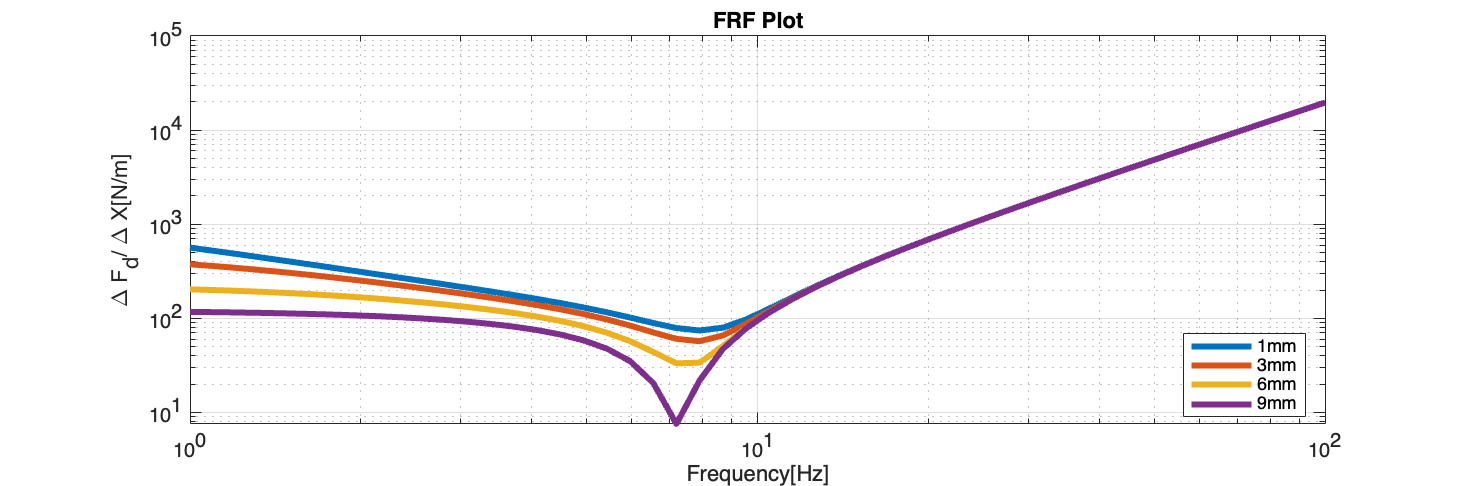


loglog(fr, EQ3_1, fr, EQ3_3, fr, EQ3_6, fr, EQ3_9, 'LineWidth', 3)
grid

legend(["1mm" "3mm" "6mm" "9mm"], Location="best")

xlabel('Frequency[Hz]') 
ylabel('\Delta F_d/ \Delta X[N/m]') 
title('FRF Plot')